clc; clear;

% read image
image= imread('Y8.jpg');
%change to binary image
bw = im2bw(image,0.60);
%plot original image
subplot(1,3,1);
imshow(image);
label = bwlabel(bw);
%measure solidity and area of tumor
stats = regionprops(label, 'Solidity', 'Area');
density = [stats.Solidity];
area = [stats.Area];
%filter out areas of low density
denseArea = density > 0.25;
%findest largest occurence of acceptable density
largestArea = max(area(denseArea));
%outline tumor
tumorOutline = find(area == largestArea);
finalTumor = ismember(label, tumorOutline);
se = strel('diamond',5)

se = strel is a diamond shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


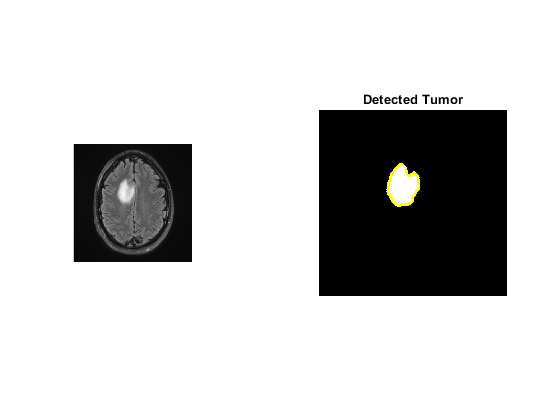

finalTumor = imdilate(finalTumor,se);
%plot just outlined tumor
subplot(1,2,2);
imshow(finalTumor,[]);
[B,L]= bwboundaries(finalTumor,'noholes');
hold on
for i = 1:length(B)
    plot(B{i}(:,2),B{i}(:,1),'y','linewidth',2);
end
title('Detected Tumor');
hold off


% create another variable of original image
Image= image;

%convert image to gray-scale
Image = rgb2gray(Image);

% sobel edge dectection
[~,threshold] = edge(Image, 'sobel');
fudgeFactor = 0.5;
Imageedge = edge(Image,'sobel', threshold*fudgeFactor);

% dilate image
se90 = strel('line',3,90);
se0 = strel('line',3,0);
Imagedilated = imdilate(Imageedge,[se90,se0]);
% fill gaps in the tumor
Imagefilled = imfill(Imagedilated,'holes');
%clear borders
Imagenobord = imclearborder(Imagefilled,4);
% smooth tumor edges
seD = strel('diamond',1);
% smoothen image
Imagefinal = imerode(Imagenobord,seD);
Imagefinal = imerode(Imagefinal,seD);
%find area of the brain and tumors(white pixels)
tumorArea = nnz(finalTumor);
brainArea = nnz(Image);
%calculate percentage covered by tumor

5222

200699

fprintf('Percentage of Brain Covered by Tumor: %0.3f',tumorArea/brainArea*100);

Percentage of Brain Covered by Tumor: 2.602